# Lab 5- Bar Yerushalmian and Ben Efrat

clear , clc;

## part 1

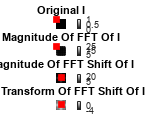

%%%1
I = zeros(41);
I(1:5,1:5) = 255;
I = logical(I);

%%%2
FFT1 = fft2(I);
FFT1_Shift = fftshift(FFT1);


fi=figure();
subplot(4,1,1)
imshow(I)
title("Original I");
colorbar
hold on;
plot(1,1, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,2)
imshow(abs(FFT1),[])
colorbar
title("Magnitude Of FFT Of I")
hold on;
plot(1,1, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,3)
imshow(abs(FFT1_Shift),[])
title("Magnitude Of FFT Shift Of I")
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,4)
imshow(log(abs(FFT1_Shift)),[])
title("Log Transform Of FFT Shift Of I")
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);
saveas(fi,"0FFT1_fig",'jpg');

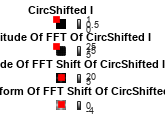


%%%3
CircShiftI = circshift(I,[-2 -2]);
%imshow(CircShiftI)
FFT2 = fft2(CircShiftI);
FFT2_Shift = fftshift(FFT2);


fi=figure();
subplot(4,1,1)
imshow(CircShiftI)
title("CircShifted I");
colorbar
hold on;
plot(1,1, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,2)
imshow(abs(FFT2),[])
colorbar
title("Magnitude Of FFT Of CircShifted I")
hold on;
plot(1,1, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,3)
imshow(abs(FFT2_Shift),[])
title("Magnitude Of FFT Shift Of CircShifted I")
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,4)
imshow(log(abs(FFT2_Shift)),[])
title("Log Transform Of FFT Shift Of CircShifted I")
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);
saveas(fi,"1FFT2_fig",'jpg');

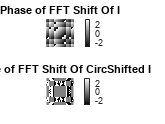


%%%4

fi=figure();
subplot(2,1,1)
imshow(angle(FFT1_Shift),[]); % Linear Phase 
title("Phase of FFT Shift Of I");
colorbar
subplot(2,1,2)
imshow(angle(FFT2_Shift),[]);
title("Phase of FFT Shift Of CircShifted I"); % Zero Phase 
colorbar
saveas(fi,"3phase_fig",'jpg');

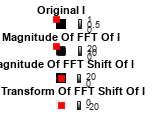


%%%5

I = zeros(40);
I(1:5,1:5) = 255;
I = logical(I);

FFT3 = fft2(I);
FFT3_Shift = fftshift(FFT3);


fi=figure();
subplot(4,1,1)
imshow(I)
title("Original I");
colorbar
hold on;
plot(1,1, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,2)
imshow(abs(FFT3),[])
colorbar
title("Magnitude Of FFT Of I");
hold on;
plot(1,1, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,3)
imshow(abs(FFT3_Shift),[])
title("Magnitude Of FFT Shift Of I");
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,4)
imshow(log(abs(FFT3_Shift)),[])
title("Log Transform Of FFT Shift Of I");
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);
saveas(fi,"4FFT3_fig",'jpg');

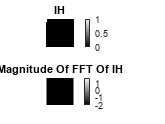



%%%6

% Create IV 
I = zeros(41);
I(1,1:5) = 255;
IV = logical(I);

% Create IH
I = zeros(41);
I(1:5,1) = 255;
IH = logical(I);

%%%7+8
%FFT IH
FyIh = fft(IH);
FyIh = fftshift(FyIh);

%FFT IV
FxIv = fft(IV');
FxIv = FxIv';
FxIv = fftshift(FxIv);

%PLOTTING IH
fi=figure();
subplot(2,1,1)
imshow(IH)
title("IH");
colorbar

subplot(2,1,2)
imshow(log(abs(FyIh)),[])
colorbar
title("Magnitude Of FFT Of IH")

saveas(fi,"5IH_fig",'jpg');

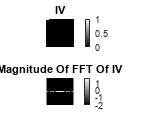


%PLOTTING IV

fi=figure();
subplot(2,1,1)
imshow(IV)
title("IV");
colorbar

subplot(2,1,2)
imshow(log(abs(FxIv)),[])
colorbar
title("Magnitude Of FFT Of IV")
saveas(fi,"6IV_fig",'jpg');

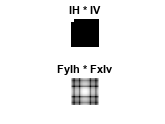


%%%9
Res = IH*IV;
fi=figure();
subplot(2,1,1)
imshow(Res,[])
title("IH * IV")

Fourier_Transorm_Res = FyIh*FxIv;
subplot(2,1,2)
imshow(log(abs(Fourier_Transorm_Res)),[])
title("FyIh * FxIv")
saveas(fi,"7multiply_fig",'jpg');

## part 2

clear , clc

Epsilon = 0.001;
load lab5.mat vn1
[x1,y1] = size(vn1);
I = zeros(x1,y1);

% Clear cross
Icross = zeros(x1,y1);
Icross(26:36,34:36) = 255;
Icross(30:32,30:40) = 255;

% Blurred cross
Crop = imcrop(vn1,[26 26 18 10]);
I(26:36,26:44) = Crop; % blurred cross image

% Blurring function calculation
FFT_Icross = fft2(Icross); %% FFT of FIXED cross
FFT_Crop = fft2(I); % FFT of blurred cross
FFT_vn1 = fft2(vn1); % FFT of blurred image

H = FFT_Crop./FFT_Icross;

[x2,y2]=size(H);

%Restoring filter
for i = 1:x2
    for j = 1:y2
        if(abs(H(i,j)) > Epsilon)
            R(i,j) = 1/H(i,j);
        else
            R(i,j) = 0;
        end
    end
end

FFT_Fixed_I = FFT_vn1.*R;

Fixed_I = ifft2(FFT_Fixed_I);
fi=figure();
subplot(2,3,1)
imshow(vn1,[]);
title("Original I")
subplot(2,3,2)
imshow(Fixed_I,[]);
title("FIxed I")
subplot(2,3,3)
imshow(abs(H),[])
title("Blurring Filter (H)")

subplot(2,3,4)
h = ifft(H);
imshow(h,[]);

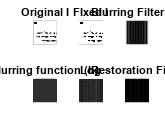

title("Blurring function (h)");

subplot(2,3,5);
imshow(log(abs(h)),[]);
title("Log Tramsform of h");

subplot(2,3,6)
imshow(abs(R),[])
title("Restoration Filter")
saveas(fi,"8BlurringFilter_fig",'jpg');